close all
clear variables

spectra=importdata('spectra.csv');
lambdaStart=importdata('lambda_start.csv');
lambdaDelta=importdata('lambda_delta.csv');
starNames=importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


lambdaPr=656.28

lambdaPr = 656.2800

speedOfLight=299792.458

speedOfLight = 2.9979e+05

nObs=size(spectra,1)

nObs = 357

nStar=size(spectra,2)

nStar = 7

lambdaEnd=lambdaStart + (nObs-1)*lambdaDelta;
lambda = (lambdaStart:lambdaDelta:lambdaEnd)';
movaway=[]


movaway =

     []



fg1=figure;
xlabel("Длина волны, нм")
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
text(631.5, 3.25*10^(-13),'Ярышева Ирина, Б04-005')
title({'Спектры звезды'})
grid on
hold on
for i=1:nStar
    s=spectra(:,i);
    [sHa,idx]=min(s);
    lambdaHa=lambda(idx);
    z=(lambdaHa/lambdaPr)-1;
    speed(i,:)=z*speedOfLight;
    if speed(i,:)>0
        plot(lambda,s,'LineWidth', 3)
        movaway = [movaway; starNames(i, :)]
    else
        plot(lambda,s,'--','LineWidth', 1)
    end
end

movaway = 1×1 cell array
    {'HD5211'}


movaway = 2×1 cell array
    {'HD5211' }
    {'HD56030'}


movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


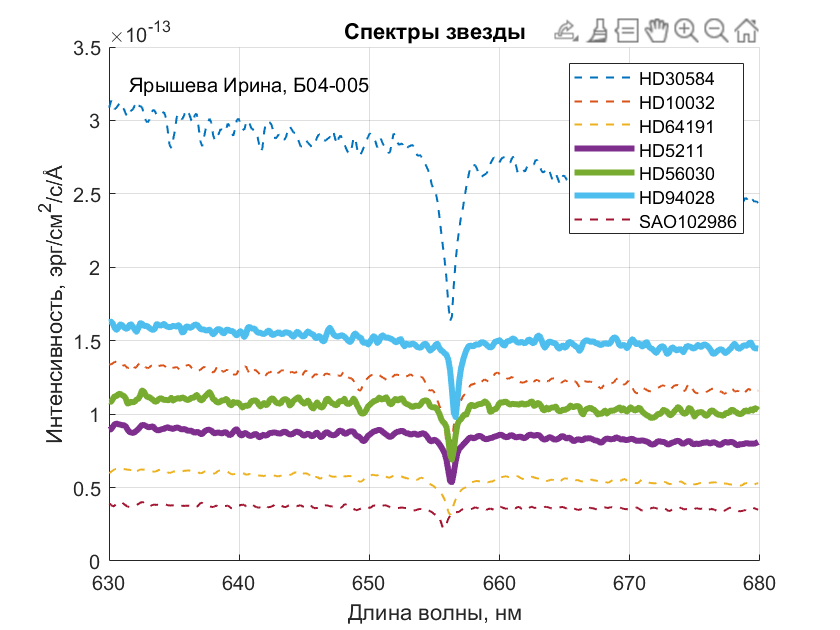

legend(starNames)
hold off
set(fg1, 'visible', 'on')
saveas(fg1,"spectra.jpg")